
clear all;
close all;
colors=npg(10); % Ten basic colors

maindir='\\Artemis-pc\Data\2026-06-11\';
%maindir='C:\Users\USTC\Desktop\BxByScan\';
%load([maindir,'BxByScan.mat']);

save_data = 0;



% [Bx By] %

% BxBy = 1e-3.*...   % mA
%     -[[150 -500]; ...
%     [250 -400]; [250 -450]; [250 -500]; [250 -550]; [250 -600]; ...
%     [350 -350]; [350 -400]; [350 -490]; [350 -500]; [350 -600]; [350 -650]; ...
%     [450 -400]; [450 -500]; [450 -600]; ...
%     [550 -500]; [550 -600]];
% 
% ratio = [[0.725974 0.725984]; ...
%     [0.726026 0.726030]; [0.726048 0.726037]; [0.726054 0.726036]; [0.726037 0.726031]; [0.726021 0.726007];...
%     [0.726020 0.726012]; [0.726032 0.726038]; [0.726070 0.726053]; [0.726076 0.726049]; [0.726036 0.726020]; [0.726046 0.726025]; ...
%     [0.726018 0.726004]; [0.726051 0.726043]; [0.726041 0.726013]; ...
%     [0.725987 0.725987]; [0.725957 0.725961]];
% 
% err = [[4 4]; ...
%     [3 3]; [3 2]; [3 3]; [3 2]; [4 3]; ...
%     [2 2]; [4 3]; [3 3]; [3 3]; [3 3]; [3 3]; ...
%     [3 3]; [3 3]; [3 4]; ...
%     [4 3]; [4 4]]*1e-6;
% 
% Bx = BxBy(:,1);
% By = BxBy(:,2);

% ratio_mean = sum(ratio.*weight)./sum(weight);
% err_mean = sqrt(sum(weight.* ((ratio-ratio_mean).^2 + 1./weight)) ./ sum(weight));



Bx = 1e-3*([-200 0 100 200 300 ...
    -200:100:500]-300);   % mA
By = 1e-3*([3200*ones(1,5) ...
    3300*ones(1,8)]-3300);   % mA
ratio = [0.7260300 0.7260503 0.7260579 0.7260730 0.7260302 ...
    0.7260897 0.7261005 0.7260529 0.7260468 0.7260679 0.7260422 0.7260774 0.7260906];
err = 1e-7*[11 31 32 33 43 ...
    80 47 89 60 89 62 64 73];

weight = 1./err.^2;


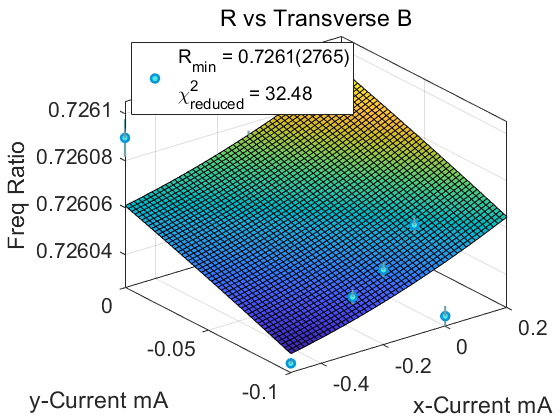


%% 拟合: '无标题拟合 1'。

[xData, yData, zData, weights] = prepareSurfaceData(Bx.*1e-0, By.*1e-0, ratio, weight);

% 设置 fittype 和选项。
ft1 = fittype( 'a1*(x-c1)^2+a2*(y-c2)^2+d',...
    'independent', {'x', 'y'}, 'dependent', 'z' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [-2 -2 -1 -1 0.725];
opts1.Upper = [1 1 1 1 0.727];
opts1.StartPoint = [-1e-10 -1e-10 -0.3 0.6 0.726];
opts1.Weights = weights;

% 对数据进行模型拟合。
[fitresult1, gof1] = fit( [xData, yData], zData, ft1, opts1 );
c1 = fitresult1.c1;
c2 = fitresult1.c2;
R_min = fitresult1.d;

interval = confint(fitresult1);
c1_sigma = (interval(2,3)-interval(1,3))/4;
c2_sigma = (interval(2,4)-interval(1,4))/4;
R_sigma = (interval(2,5)-interval(1,5))/4;



% 计算 Chi square %
chi_square1 = 0;
for k1 = 1:length(ratio)
    temp1(k1) = ( ratio(k1)-fitresult1(Bx(k1),By(k1)) )^2;
    chi_square1 = chi_square1 + weight(k1)*temp1(k1);
end
chi_square1 = chi_square1/(length(ratio)-5);


%% 绘制拟合曲面 %%

f1 = figure;

s1 = plot( fitresult1, [Bx;By]' , ratio' );
s1(2).MarkerEdgeColor = [0.04 0.59 0.83];
s1(2).MarkerFaceColor = [0.29 0.91 0.91];
s1(2).LineWidth = 2;


%% 绘制原始数据 %%

%E1 = plot3(BxBy(:,1), BxBy(:,2), ratio_mean,'o','markersize',6,...
%    'MarkerEdgeColor',[0.04,0.59,0.83],'MarkerFaceColor',[0.29,0.91,0.91]);

hold on;
for k = 1:length(ratio)
    plot3([Bx(k),Bx(k)], [By(k),By(k)],[-err(k),err(k)]+ratio(k),...
        '-','Color',[0.45 0.63 0.67],'LineWidth',1.6);
end

title('R vs Transverse B','FontName','times new roman');
xlabel('x-Current mA');
ylabel('y-Current mA');
zlabel('Freq Ratio');

set(gca,'FontName','FontName','FontSize',16);


legend(['R_{min} = ',num2str(roundn(R_min,-4),'%.4f'),'(',num2str(round(R_sigma*1e4)),')', ...
    newline '\chi^2_{reduced} = ',num2str(roundn(chi_square1,-2),'%.2f')], ...
    'Location','best','FontSize',14);


set(gcf,'Visible','on');


if save_data == 1
    saveas(f1,[maindir,'BxByScan.fig']); 
    saveas(f1,[maindir,'BxByScan.png']);
    
    save([maindir,'BxByScan.mat']);
end